Load the MRI:

clear all;
MRIstruct=load("MRI_example.mat");
MRI=MRIstruct.mri;
p=[0.1,9,3,45,5,7];
M = createMatrix(p);

Apply - with arbitrarily chosen parameters - the rototranslation matrix to the provided MRI volume to obtain its rototranslated version. This requires the creation of a Matlab function of such kind: Function mri_out = rotateVolume(M,mri_in,x,y,z) Input: M = 4x4 rototranslation matrix mri_in = input mri volume to be rotated x,y,z = coordinates in which the volume is defined Output: Mri_out = output mri volume rototranslated

% Define the coordinates of the volume
x = -round(size(MRI,1)/2)+1:round(size(MRI,1)/2);
y = -round(size(MRI,1)/2)+1:round(size(MRI,2)/2); 
z = -round(size(MRI,1)/2)+1:round(size(MRI,3)/2);
% Apply the rototranslation matrix to the MRI volume
mri_out = rotateVolume(M, MRI, x, y, z);

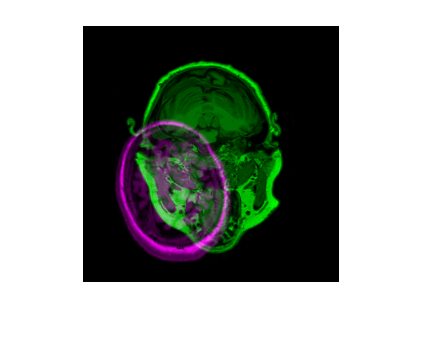


% Display the original and rotated MRI volumes side by side
figure
imshowpair(MRI(:,:,100),mri_out(:,:,100));

nbins=100;
%here we calculate the mutual information
MI = mutualInfo(MRI,mri_out,nbins);

nscales = 4;
[X{nscales},Y{nscales},Z{nscales}] =meshgrid(x,y,z);
vol{nscales} = MRI;
vol_rototranslated{nscales} = mri_out;

%we create 4 empty volumes with the correct dimensions

for i = nscales - 1:-1:1
    vol{i} = smooth3(vol{i+1},'guassian',[5 5 5]);
    vol_rototranslated{i} = smooth3(vol_rototranslated{i+1},'guassian',[5 5 5]);
    [X{i},Y{i},Z{i},vol{i}] = reducevolume(X{i+1},Y{i+1},Z{i+1},vol{i},[2 2 2]);
    [X{i},Y{i},Z{i},vol_rototranslated{i}] = reducevolume(X{i+1},Y{i+1},Z{i+1},vol_rototranslated{i},[2 2 2]);
end

p = zeros(1,6);
m = createMatrix(p);
Mf=m;

%for each reduced volume we calculate the best inverse rototranslation
%matrix to go back to the original MRI

for i = 1:(nscales -2)
    x = X{i}(1,:,1);
    y = Y{i}(:,1,1);
    z = squeeze(Z{i}(1,1,:));
    vol_rototranslated{i} = rotateVolume(inv(Mf),vol_rototranslated{i},x,y,z);
    figure
    options = psoptimset('InitialMeshSize',0.03,'MaxIter',100,'TolCon',1e-5,'TolMesh',5e-5,'TolX',1e-6,'PlotFcns',{@psplotbestf,@psplotbestx}); 
    %optimise 
    [p, MI_norm_neg, exitflag_len] = patternsearch(@(p)functional(p,vol{i}, vol_rototranslated{i},x,y,z,length(z)/2), ...
        [0;0;0;0;0;0],[],[],[],[],[-pi/2;-pi/2;- pi/2;min(x(:));min(y(:));min(z(:))],[pi/2;pi/2;pi/2;max(x(:));max(y(:));max(z(:) )],options);
%     M_opt=createMatrix(param(1:6));
%     mri_out_optimized=rotateVolume(M_opt,MRIsmooth,x,y,z);
   m=createMatrix(p');
   Mf=m*Mf;    
end

patternsearch stopped because the mesh size was less than options.MeshTolerance.
patternsearch stopped by the output or plot function.


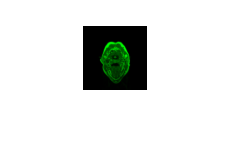

vol_rototranslated{i} = rotateVolume(inv(Mf),vol_rototranslated{i},x,y,z);
figure
imshowpair(vol{i}(:,:,256/pow2(2,nscales-i+1)),vol_rototranslated{i}(:,:,256/pow2(2,nscales-i+1)));

Define a desired rototranslation matrix by choosing the three rotation angles around the three Cartesian axes (X, Y, Z) and the translation vector. This requires the creation of a Matlab function having the following prototype: Function M = createMatrix(p) Input: p = 6x1 vector with rotation and translation parameters [θx;θy;θz;sx;sy;sz;]. Output: M = 4x4 rototranslation matrix:

function M = createMatrix(p)
    % Extract rotation and translation parameters from input vector
    theta = p(1:3);%in radians
    scale = [p(4:6)'; 1];%in whatever length measure unit
    m_x = [    1              0                0        ;
        0           cos(theta(1))  sin(theta(1))        ;...
               0          -sin(theta(1))  cos(theta(1)) ;...
               0               0               0            ];

    m_y = [cos(theta(2))      0         -sin(theta(2))   ;...
               0              1             0            ;...
           sin(theta(2))      0          cos(theta(2))   ;...
               0              0             0                ];

    m_z = [cos(theta(3))   sin(theta(3))       0         ;...
           -sin(theta(3))  cos(theta(3))       0         ;...
               0               0               1         ;...
               0               0               0             ];

    M = [m_x scale] * [m_y scale] *[m_z scale];
end


function mri_out = rotateVolume(M,MRI,x,y,z)
    % Input: M = 4x4 rototranslation matrix
    % mri_in = input mri volume to be rotate
    % x,y,z = coordinates in which the volume is defined
    % Output: mri_out = output mri volume rototranslated
    [x_i,y_i,z_i] = meshgrid(x,y,z);
    points_in = [x_i(:), y_i(:), z_i(:), ones(numel(x_i),1)]';

    % Apply the rototranslation matrix to the coordinate vector
    points_out = M * points_in;
    x_out = reshape(points_out(1,:),size(x_i));
    y_out = reshape(points_out(2,:),size(x_i));
    z_out = reshape(points_out(3,:),size(x_i));


    % Interpolate the input volume at the rotated coordinates
    mri_out = interp3(x_i,y_i,z_i,MRI,x_out,y_out,z_out);
    % Reshape the output volume to the original size
    %mri_out = reshape(mri_out,size(X));
    mri_out(isnan(mri_out))=0;
end


function MI = functional(p,MRI,mri_out,x,y,z,nbins)
% Input: p = 6x1 vector with rotation and translation parameters [θx;θy;θz;sx;sy;sz;] 
% mri1,mri2 = mri volumes of which you must calculate the MI x,y,z = coordinates in which the volume is defined 
% nbins = number of bins with which you must calculate the probability densities 
% of individual volumes and the joint probability density probability density necessary for the calculation of the MI 
 M = inv(createMatrix(p'));
 mri_rot = rotateVolume(inv(M),mri_out,x,y,z);
 MI = 1-mutualInfo(MRI,mri_rot,nbins);
end
 


function MI = mutualInfo(MRI,mri_out,nbins)
    % Input: mri1,mri2 = mri volumes of which you must calculate MI
    % nbins = number of bins with which you must  calculate the probability densities of the individual volumes and the joint probability density needed to calculate the MI through the formula: 
    % MI = H1 + H2 - H12
    % Where H1, H2, and H12 are the marginal and joint entropies, respectively
    % Calculate the histograms of the individual volumes
    h1 = hist(MRI(:),nbins);
    h2 = hist(MRI(:),nbins);

    % Normalize the histograms to get probability densities
     h1 = h1/sum(h1);
     h2 = h2/sum(h2);

    % Calculate the joint histogram of the two volumes
    h12 = hist3([MRI(:), mri_out(:)],[nbins nbins]);

    % Normalize the joint histogram to get joint probability density
     h12 = h12/sum(sum(h12));

    % Calculate the marginal entropies
    H1 = -nansum(h1.*log(h1));     H2 = -nansum(h2.*log(h2));
    
    % Calculate the joint entropy
    H12 = -nansum(nansum(h12.*log(h12)));
    % Calculate the mutual information
    MI = (H1+H2-H12)./max(H1,H2);
end
